# 3D Simulation of path planning algorithms

This model simulates drone movement in 2d space

## Creating Environment

Scenario = uavScenario("UpdateRate",100,"ReferenceLocation",[0 0 0]);

Add Drone

InitialPosition = [0 0 -1];
InitialOrientation = [0 0 0];
platUAV = uavPlatform("UAV",Scenario, ...
                      "ReferenceFrame","NED", ...
                      "InitialPosition",InitialPosition, ...
                      "InitialOrientation",eul2quat(InitialOrientation));
updateMesh(platUAV,"quadrotor",{1.2},[0 0 1],eul2tform([0 0 pi]));

## Setting Parameters

% Size of the ground
planex = 12.5;           % m
planey = 8.5;            % m
planedepth = 0.2;        % m, distance from plane to the reference frame

% Battery Capacity
battery_capacity = 7.6*3;

%% Material Property
% Assuming the arm of the drone is manufractured by 3D Printing, the ideal
% material is PLA, safe, light and cheap, the only concern is its thermal
% property
rho_pla   = 1.25;            % g/cm^3 

% Measured drone mass
drone_mass = 1.2726;


%% Propeller parameters
propeller.diameter = 0.254; % m
propeller.Kthrust  = 0.1072; 
propeller.Kdrag    = 0.01;

air_rho            = 1.225;  % kg/m^3
air_temperature    = 273+25; % degK
wind_speed         = 0;      % Wind speed (m/s)

%% Leg parameters
drone_leg.Extr_Data = flipud([...
    0     0;
    0.5   0;
    1    -1;
    0.98 -1;
    0.5  -0.02;
   -0.5  -0.02;
   -0.98 -1;
   -1    -1;
   -0.5   0].*[1 1]*0.15);

drone_leg.width = 0.01;

%% Motor parameters
qc_motor.max_torque = 0.8;  % N*m
qc_motor.max_power  = 160;  % W
qc_motor.time_const = 0.02; % sec
qc_motor.efficiency = 25/30*100; % 0-100
qc_motor.efficiency_spd = 5000; % rpm
qc_motor.efficiency_trq = 0.05; % N*m
qc_motor.rotor_damping  = 1e-7; % N*m/(rad/s)

qc_max_power = qc_motor.max_power;

%% Controller parameters
filtM_position = 0.005;
kp_position    = 8;
ki_position    = 0.04;
kd_position    = 3.2;
filtD_position = 100;
pos2attitude   = 2.4;

filtM_attitude = 0.01;
kp_attitude    = 128.505;
ki_attitude    = 5.9203;
kd_attitude    = 78.2000*2;
filtD_attitude = 1000;
limit_attitude = 800;

filtM_yaw      = 0.01;
kp_yaw         = 25.7010*4*2;
ki_yaw         = 5.9203*0.01;
kd_yaw         = 78.2000*0.01;
filtD_yaw      = 100;
limit_yaw      = 20;

filtM_altitude = 0.05;
kp_altitude    = 0.27;
ki_altitude    = 0.07;
kd_altitude    = 0.35;
filtD_altitude = 10000;
limit_altitude = 10;

kp_motor       = 0.00375;
ki_motor       = 4.50000e-4;
kd_motor       = 0;
filtD_motor    = 10000;
filtSpd_motor    = 0.001;
limit_motor    = 0.25;

%% Drag coefficients
qd_drag.Cd_X = 0.35;
qd_drag.Cd_Y = 0.35;
qd_drag.Cd_Z = 0.6;
qd_drag.Roll = 0.2;
qd_drag.Pitch = 0.2;
qd_drag.Yaw = 0.2;
qd_area.YZ = 0.0875;
qd_area.XZ = 0.0900;
qd_area.XY = 0.2560;
qd_area.Roll = qd_area.XY*2;
qd_area.Pitch = qd_area.XY*2;
qd_area.Yaw = qd_area.XY;

% Add waypoint

## Setting Up Waypoint Map

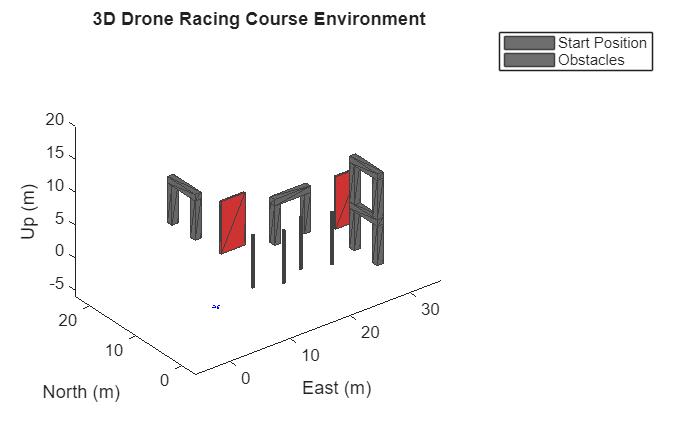

% =============================
% === Course Geometry Params ===
% =============================
wallHeight = 8;
wallThickness = 0.3;
poleHeight = 8;
poleRadius = 0.2;

% =============================
% === 1. Bridges (with ladder option) ===
% =============================
BridgePositions = [25 0; 20 10; 10 20];
BridgeAngles = [90 0 90];
BridgeLength = 6;
BridgeWidth  = 1;
BridgeHeight = 6;
DeckThickness = 1;
SupportHeight = BridgeHeight;
SupportWidth  = 1;

% NEW: Specify which bridges are ladders (1 = ladder, 0 = regular)
BridgeIsLadder = [1 0 0];   % First bridge is a ladder

for i = 1:size(BridgePositions,1)
    baseCoords = [-BridgeLength/2, -BridgeWidth/2;
                   BridgeLength/2, -BridgeWidth/2;
                   BridgeLength/2,  BridgeWidth/2;
                  -BridgeLength/2,  BridgeWidth/2];
    theta = deg2rad(BridgeAngles(i));
    R = [cos(theta) -sin(theta); sin(theta) cos(theta)];
    rotatedCoords = (R * baseCoords')';
    deckXY = rotatedCoords + BridgePositions(i,:);
    deckZ = [BridgeHeight, BridgeHeight + DeckThickness]; % Row vector

    % --- Draw base deck ---
    addMesh(Scenario,"polygon",{deckXY, deckZ}, [0.4 0.4 0.4]);

    % --- Add supports for the base deck ---
    supportOffsets = [-BridgeLength/2 + SupportWidth/2, 0;
                       BridgeLength/2 - SupportWidth/2, 0];
    rotatedSupportOffsets = (R * supportOffsets')';
    for s = 1:2
        sx = BridgePositions(i,1) + rotatedSupportOffsets(s,1);
        sy = BridgePositions(i,2) + rotatedSupportOffsets(s,2);
        supportXY = [sx - SupportWidth/2, sy - SupportWidth/2;
                     sx + SupportWidth/2, sy - SupportWidth/2;
                     sx + SupportWidth/2, sy + SupportWidth/2;
                     sx - SupportWidth/2, sy + SupportWidth/2];
        addMesh(Scenario,"polygon",{supportXY, [0, SupportHeight]}, [0.4 0.4 0.4]);
    end

    % =============================
    % === Ladder Extension (optional) ===
    % =============================
    if BridgeIsLadder(i) == 1
        % Top supports start above first deck
        topSupportBottomZ = SupportHeight + DeckThickness;
        topSupportTopZ = topSupportBottomZ + SupportHeight;

        % --- Add second layer of supports ---
        for s = 1:2
            sx = BridgePositions(i,1) + rotatedSupportOffsets(s,1);
            sy = BridgePositions(i,2) + rotatedSupportOffsets(s,2);
            supportXY = [sx - SupportWidth/2, sy - SupportWidth/2;
                         sx + SupportWidth/2, sy - SupportWidth/2;
                         sx + SupportWidth/2, sy + SupportWidth/2;
                         sx - SupportWidth/2, sy + SupportWidth/2];
            addMesh(Scenario,"polygon",{supportXY, [topSupportBottomZ, topSupportTopZ]}, [0.4 0.4 0.4]);
        end

        % --- Add second (upper) deck ---
        upperDeckZ = [topSupportTopZ, topSupportTopZ + DeckThickness];
        addMesh(Scenario,"polygon",{deckXY, upperDeckZ}, [0.4 0.4 0.4]);
    end
end



% =============================
% === 4. Walls ===
% =============================
WallPositions = [12 12; 28 8];
for i = 1:size(WallPositions,1)
    cx = WallPositions(i,1);
    cy = WallPositions(i,2);
    wallXY = [cx-2, cy; cx+2, cy; cx+2, cy+wallThickness; cx-2, cy+wallThickness];
    addMesh(Scenario,"polygon",{wallXY, [0 wallHeight]}, [0.8 0.2 0.2]);
end

% =============================
% === 5. Poles ===
% =============================
PolePositions = [8 2.5; 12 1; 16 2.5; 20 1];
for i = 1:size(PolePositions,1)
    cx = PolePositions(i,1);
    cy = PolePositions(i,2);
    addMesh(Scenario, "cylinder", {[cx, cy, poleRadius], [0, poleHeight]}, [1 1 0]);
end

% =============================
% === Visualization ===
% =============================
show3D(Scenario);
legend("Start Position","Obstacles")
title("3D Drone Racing Course Environment")

## Opening Drone System

open_system("QuadcopterModel.slx");